# **Symb_model_3link**

# 1) Lagrangian Model

This code is used to derive the differential equations of motion for the 3-link stiff-legged walker.

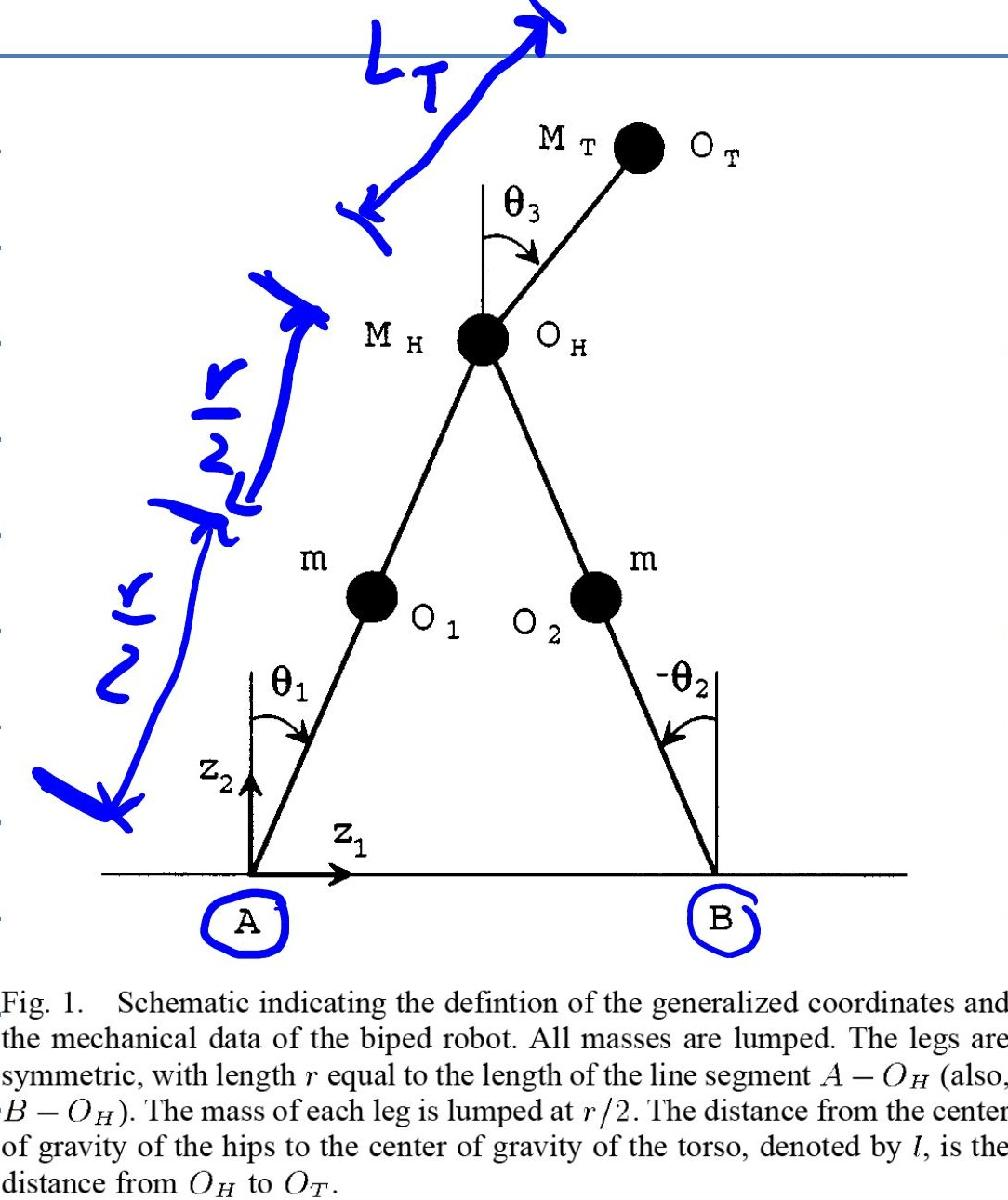

clear
syms theta_1 theta_2 theta_3 real               % configuration variables
syms d_theta_1 d_theta_2 d_theta_3 real ;       % configuration variables (time derivatives)
syms r r_T m m_H m_T g real;                    % geometric variables

## Variable Descriptions

% theta_1   - absolute angle of stance leg (1) from the vertical (cw positive)
% theta_2   - absolute angle of swing leg (2) from the vertical (cw positive)
% theta_3   - absolute angle of torso (cw positive)
% d_theta_1 - time derivative of theta_1
% d_theta_2 - time derivative of theta_2
% d_theta_3 - time derivative of theta_3
% "" for the second time derivatives
% r         - length of leg from foot to hip
% r_T       - length of torso from hip to torso
% m         - mass of knee revolute joints
% m_H       - mass of hip revolute joint
% m_T       - mass of torso joint
% g         - gravitational constant


## Generalized coordinates and velocities

q = [theta_1 theta_2 theta_3].' ;           % 3 x 1 vector
d_q = [d_theta_1 d_theta_2 d_theta_3].' ;   % 3 x 1 vector (time derivative of q)

## Positions

p_1f = [0 0].' ;                                        % position of stance (1) foot
p_1k = p_1f + (r/2)*[sin(theta_1) ; cos(theta_1)] ;     % "" stance (1) knee
p_H = p_1f + r*[sin(theta_1) ; cos(theta_1)] ;          % "" hip
p_T = p_H + r_T*[sin(theta_3) ; cos(theta_3)] ;         % "" torso
p_2f = p_H + r*[-sin(theta_2) ; -cos(theta_2)] ;        % "" swing (2) foot
p_2k = p_H + (r/2)*[-sin(theta_2) ; -cos(theta_2)] ;    % "" swing (2) knee

## Velocities

v_1k = jacobian(p_1k,q)*d_q ;   % velocity of stance (1) knee mass
v_H = jacobian(p_H,q)*d_q ;     % "" hip mass
v_T = jacobian(p_T,q)*d_q ;     % "" torso mass
v_2k = jacobian(p_2k,q)*d_q ;   % "" swing (2) knee mass

## Potential Energy - Energy of position

Ve_1k = m*g*p_1k(2) ;   % PE of stance (1) knee mass
Ve_H = m_H*g*p_H(2) ;   % "" hip mass
Ve_T = m_T*g*p_T(2) ;   % "" torso mass
Ve_2k = m*g*p_2k(2) ;   % "" swing (2) knee mass
V = simplify(Ve_1k + Ve_H + Ve_2k + Ve_T) ;    % Total potential energy

## Kinetic Energy - Energy of velocity

K_1k = simplify((1/2)*m*(v_1k).'*v_1k) ;           % KE of stance (1) knee mass
K_H = simplify((1/2)*m_H*(v_H).'*v_H) ;            % "" hip mass
K_T = simplify(expand((1/2)*m_T*(v_T).'*v_T)) ;    % "" torso mass
K_2k = simplify(expand((1/2)*m*(v_2k).'*(v_2k))) ; % "" swing (2) knee mass
K = simplify(K_1k + K_H + K_T + K_2k) ;         % Total kinetic energy


## The Lagrangian 

L = K - V ;     % the Lagrangian

**End Goal: Lagrange's Equations**

        $\frac{d}{\mathrm{dt}}\frac{\partial L}{\partial {\overset{\cdot }{q} }_i }-\frac{\partial L}{\partial q}=\Gamma_i$       **(1.1)                   **where,               $L=K-V$       **(1.2)**

## Kinetic Energy - derivation with mass-inertia matrix

$K_i =\frac{1}{2}m_i v_i^T v_i$  **(1.3)**     and   $v_i =\frac{d}{\mathrm{dt}}p_i =\left(\frac{\partial }{\partial q}p_i \right)\overset{\cdot }{q}$    **(1.4) **$\longrightarrow$     $K_i =\frac{1}{2}m_i {\overset{\cdot }{q} }^T {\left\lbrack \frac{\partial p_i }{\partial q}\right\rbrack }^T \left\lbrack \frac{\partial p_i }{\partial q}\right\rbrack \overset{\cdot }{q}$

Rearranging Ki yields

        $K_i =\frac{1}{2}{\overset{\cdot }{q} }^T \left\lbrack {m_i \left\lbrack \frac{\partial p_i }{\partial q}\right\rbrack }^T \left\lbrack \frac{\partial p_i }{\partial q}\right\rbrack \right\rbrack \overset{\cdot }{q}$        **(1.5)**

Note: 

        $D_i \left(q\right)={m_i \left\lbrack \frac{\partial p_i }{\partial q}\right\rbrack }^T \left\lbrack \frac{\partial p_i }{\partial q}\right\rbrack$  **(1.6)**  $\longrightarrow$ mass-inertia matrix

- n x n matrix

- symmetric

- quadratic form

Therefore

        $K_i =\frac{1}{2}{\overset{\cdot }{q} }^T D_i \left(q\right)\overset{\cdot }{q}$     **(1.7)**

## Mass-inertia matrix computations

D_1k = simplify(m*(jacobian(p_1k,q)).'*jacobian(p_1k,q)) ;
D_H = simplify(m_H*(jacobian(p_H,q)).'*jacobian(p_H,q)) ;
D_T = simplify(m_T*(jacobian(p_T,q)).'*jacobian(p_T,q)) ;
D_2k = simplify(m*(jacobian(p_2k,q)).'*jacobian(p_2k,q)) ;
D = simplify(D_1k + D_H + D_T + D_2k) ; 


## Check: Kinetic Energy and mass-inertia matrix elements

% % KE check with previous KE's
% K_1k_check = simplify((1/2)*(d_q).'*D_1k*(d_q)) ;           
% K_H_check = simplify((1/2)*(d_q).'*D_H*(d_q)) ;
% K_T_check = simplify((1/2)*(d_q).'*D_T*(d_q)) ; 
% K_2k_check = simplify((1/2)*(d_q).'*D_2k*(d_q)) ;
% 
% d_1k_11 = jacobian(jacobian(K_1k_check,d_q(1)),d_q(1)) ;    % Element a_11 of D_1k matrix
% d_H_11 = jacobian(jacobian(K_H_check,d_q(1)),d_q(1)) ;      % Element a_11 of D_H matrix
% d_T_11 = jacobian(jacobian(K_T_check,d_q(1)),d_q(1)) ;      % Element a_11 of D_T matrix
% d_T_13 = jacobian(jacobian(K_T_check,d_q(3)),d_q(1)) ;      % Element a_13 (a_31) of D_T matrix
% d_T_33 = jacobian(jacobian(K_T_check,d_q(3)),d_q(3)) ;      % Element a_33 of D_T matrix
% d_2k_11 = jacobian(jacobian(K_2k_check,d_q(1)),d_q(1)) ;    % Element a_11 of D_2k matrix
% d_2k_12 = jacobian(jacobian(K_2k_check,d_q(1)),d_q(2)) ;    % Element a_12 (a_21) of D_2k matrix
% d_2k_22 = jacobian(jacobian(K_2k_check,d_q(2)),d_q(2)) ;    % Element a_22 of D_2k matrix


## Lagrange's Equations Derivations

        $\frac{d}{\mathrm{dt}}\frac{\partial L}{\partial {\overset{\cdot }{q} }_i }-\frac{\partial L}{\partial q}=\Gamma_i$**   (1.1)           **where,      $L=K-V$      **(1.2)**

Recalling Eq. (1.1) and (1.2) note the following:

        $\frac{\partial L}{\partial \overset{\cdot }{q} }=\frac{\partial }{\partial \overset{\cdot }{q} }\left\lbrack K_i -V_i \left(q\right)\right\rbrack =\frac{\partial }{\partial \overset{\cdot }{q} }\left\lbrack \frac{1}{2}{\overset{\cdot }{q} }^T D_i \left(q\right)\overset{\cdot }{q} -V_i \left(q\right)\right\rbrack$     and since    $\frac{\partial }{\partial \overset{\cdot }{q} }\left\lbrack V_i \left(q\right)\right\rbrack =0$

the equation becomes 

        
$$\frac{\partial L}{\partial \overset{\cdot }{q} }=\frac{\partial }{\partial \overset{\cdot }{q} }\left\lbrack \frac{1}{2}{\overset{\cdot }{q} }^T D_i \left(q\right)\overset{\cdot }{q} \right\rbrack$$


which is equivalent to 

        $\frac{\partial L}{\partial \overset{\cdot }{q} }=D_i \left(q\right)\overset{\cdot }{q}$       **(1.8)**

% % Proof of this fact is shown here
% dL_dqdot = simplify(expand((jacobian(K,d_q)).')) ;  
% D_times_qdot = simplify(expand(D*d_q)) ;

Similarly, the second part of Lagrange's Equation can be rewritten as:

        $\frac{\partial L}{\partial q}=\frac{\partial }{\partial q}\left\lbrack \frac{1}{2}{\overset{\cdot }{q} }^T D_i \left(q\right)\overset{\cdot }{q} -V_i \left(q\right)\right\rbrack =\frac{\partial }{\partial q}\left\lbrack \frac{1}{2}{\overset{\cdot }{q} }^T D_i \left(q\right)\overset{\cdot }{q} \right\rbrack -\frac{\partial V_i }{\partial q}$      **(1.9)**

Continuing with the derivations Lagrange's Equations can now be written as:

        
$$\frac{\mathrm{d}}{\textrm{dt}}\left(D_i \left(q\right)\overset{\cdot }{q} \right)-\left(\frac{\partial }{\partial q}\left\lbrack \frac{1}{2}{\overset{\cdot }{q} }^T D_i \left(q\right)\overset{\cdot }{q} \right\rbrack -\frac{\partial V_i }{\partial q}\right)=\Gamma_i$$


                                        
$$\downarrow$$


        
$$\frac{\partial }{\partial q}\left\lbrack D_i \left(q\right)\overset{\cdot }{q} \right\rbrack \overset{\cdot }{q} +\frac{\partial }{\partial \overset{\cdot }{q} }\left\lbrack D_i \left(q\right)\overset{\cdot }{q} \right\rbrack \overset{\cdot \cdot }{q} -\frac{\partial }{\partial q}\left\lbrack \frac{1}{2}{\overset{\cdot }{q} }^T D_i \left(q\right)\overset{\cdot }{q} \right\rbrack +\frac{\partial V_i }{\partial q}=\Gamma_i$$


                                        
$$\downarrow$$


        
$$\frac{\partial }{\partial q}\left\lbrack D_i \left(q\right)\overset{\cdot }{q} \right\rbrack \overset{\cdot }{q} +D_i \left(q\right)\overset{\cdot \cdot }{q} -\frac{\partial }{\partial q}\left\lbrack \frac{1}{2}{\overset{\cdot }{q} }^T D_i \left(q\right)\overset{\cdot }{q} \right\rbrack +\frac{\partial V_i }{\partial q}=\Gamma_i$$
  

Note:

$D_i \left(q\right)={D_i }^T \left(q\right)$     ;       $\;{\overset{\cdot }{q} }^T D_i \left(q\right)={\overset{\cdot }{q} }^T {D_i }^T \left(q\right)={\left(D_i \left(q\right)\overset{\cdot }{q} \right)}^T$      ;       $\frac{\partial }{\partial q}\left\lbrack \frac{1}{2}{f\left(q\right)}^T \overset{\cdot }{q} \right\rbrack =\frac{1}{2}{\left\lbrack \frac{\partial }{\partial q}\left\lbrack f\left(q\right)\right\rbrack \right\rbrack }^T \overset{\cdot }{q}$

As a result, Lagrange's Equation becomes:

        
$$\frac{\partial }{\partial q}\left\lbrack D_i \left(q\right)\overset{\cdot }{q} \right\rbrack \overset{\cdot }{q} +D_i \left(q\right)\overset{\cdot \cdot }{q} -\frac{1}{2}{\left\lbrack \frac{\partial }{\partial q}D_i \left(q\right)\overset{\cdot }{q} \right\rbrack }^T \overset{\cdot }{q} +\frac{\partial V_i }{\partial q}=\Gamma_i$$


Equation (10) terms can now be redefined

        $D_i \left(q\right)=\frac{\partial^2 K_i }{\partial \overset{\cdot }{q} \partial \overset{\cdot }{q} }=\mathrm{mass}-\mathrm{inertia}\;\mathrm{matrix}\;\left(n\;x\;n\right)$        **(1.11)**

        $G_i \left(q\right)=\frac{\partial V_i }{\partial q}=\mathrm{gradient}\;\mathrm{of}\;\mathrm{the}\;\mathrm{potential}\;\mathrm{energy}\;\left(n\;x\;1\right)$         **(1.12)**

        $C_i \left(q,\overset{\cdot }{q} \right)\overset{\cdot }{q} =\left(\frac{\partial }{\partial q}\left\lbrack D_i \left(q\right)\overset{\cdot }{q} \right\rbrack \overset{\cdot }{q} -\frac{1}{2}{\left\lbrack \frac{\partial }{\partial q}\left(D_i \left(q\right)\overset{\cdot }{q} \right)\right\rbrack }^T \overset{\cdot }{q} \right)=\textrm{coriolis}\;\textrm{terms}\;\left(n\;x\;n\right)*q_{\mathrm{dot}}$       **(1.13)**

        
$$\Gamma_i =\mathrm{external}\;\mathrm{forces}$$


And Lagrange's Equation becomes

        $D_i \left(q\right)\overset{\cdot \cdot }{q} +C_i \left(q,\overset{\cdot }{q} \right)\overset{\cdot }{q} +G_i \left(q\right)=\Gamma_i$        **(1.14)**

Key terms are defined below:

D;                                                                              
C_qdot = simplify(jacobian(D*d_q,q)*d_q - (1/2)*(jacobian(D*d_q,q)).'*d_q) ;   
G = simplify((jacobian(V,q)).') ;                                               

## Torque Distribution Matrix

For the case of the 3-legged walker, the external forces are motor torques located at the hip. 

        $\Gamma_i =\mathrm{B}*u$     **(1.15)**

where, B is the torque distribution matrix and u is the input torque vector.

D'Alembert's Principle (Principle of Virtual Work) shows that 

        
$$B={\left\lbrack \frac{\partial }{\partial q}\phi \right\rbrack }^T$$


***For this example (NOT CORRECT)***

- $\phi_1$*** is the angle between the torso and the stance leg ***$\longrightarrow \phi_1 =\theta_3 -\theta_1 +{180}^{\circ }$

- $\phi_2$*** is the angle between the torso and the stance leg ***$\longrightarrow \phi_2 =\theta_3 -\theta_2 +{180}^{\circ }$

        
$$B=\left\lbrack \begin{array}{cc}
-1 & 0\\
0 & -1\\
1 & 1
\end{array}\right\rbrack$$


        $D_i \left(q\right)\overset{\cdot \cdot }{q} +C_i \left(q,\overset{\cdot }{q} \right)\overset{\cdot }{q} +G_i \left(q\right)=\mathit{Bu}$        **(1.16)**

syms phi_1 phi_2 real ;
phi_1 = theta_3 - theta_1 + 180 ;
phi_2 = theta_3 - theta_2 + 180 ;
phi = [phi_1 ; phi_2] ;
B = (jacobian(phi,q)).' ;
%B = [-1 0 ; 0 -1 ; 1 1 ] 

# 2) Developing a Feedback Controller

## Method of Virtual Constraints

Control Objectives

- $\theta_3 =\theta_3^{\mathrm{desired}} =\theta_3^d \longrightarrow$the torso arm maintains a constant angle during walking

- $\theta_2 ={-\theta }_1 \longrightarrow$   Since both legs are the same length, the angles with respect to the vertical should be equal and opposite at all times

Assuming that y is the output of the system

$y=\left\lbrack \begin{array}{c}
\theta_3 -\theta_3^d \\
\theta_2 +\theta_1 
\end{array}\right\rbrack \longrightarrow \left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$ drive the output to zero, thus achieving the objective

The output (y) is a function of the generalized coordinates

        $y=h\left(q\right)$    **(2.1)**

        $\overset{\cdot }{y} =\frac{\partial h}{\partial q}\overset{\cdot }{q}$    **(2.2)**

        $\overset{\cdot \cdot }{y} =\frac{\partial }{\partial q}\left\lbrack \frac{\partial h}{\partial q}\overset{\cdot }{q} \right\rbrack \overset{\cdot }{q} +\frac{\partial h}{\partial q}\overset{\cdot \cdot }{q}$        **(2.3)**

Remember the form of Lagrange's Eq. from Eq. (1.16)   $\longrightarrow D_i \left(q\right)\overset{\cdot \cdot }{q} +C_i \left(q,\overset{\cdot }{q} \right)\overset{\cdot }{q} +G_i \left(q\right)=\mathit{Bu}$   . Rearranging for $\overset{\cdot \cdot }{q}$ yields:

        $\overset{\cdot \cdot }{q} ={D_i }^{-1} \left(q\right)\left\lbrack \mathit{Bu}-C_i \left(q,\overset{\cdot }{q} \right)\overset{\cdot }{q} -G_i \left(q\right)\right\rbrack ={D_i }^{-1} \left(q\right)\left\lbrack \mathit{Bu}\right\rbrack +{D_i }^{-1} \left(q\right)\left\lbrack -C_i \left(q,\overset{\cdot }{q} \right)\overset{\cdot }{q} -G_i \left(q\right)\right\rbrack$      **(2.4)**

Substituting (2.4) into (2.3) yields:

        $\overset{\cdot \cdot }{y} =\frac{\partial }{\partial q}\left\lbrack \frac{\partial h}{\partial q}\overset{\cdot }{q} \right\rbrack \overset{\cdot }{q} +\frac{\partial h}{\partial q}\left\lbrack {D_i }^{-1} \left(q\right)\left\lbrack -C_i \left(q,\overset{\cdot }{q} \right)\overset{\cdot }{q} -G_i \left(q\right)\right\rbrack \right\rbrack +\frac{\partial h}{\partial q}\left\lbrack {D_i }^{-1} \left(q\right)\left\lbrack \textrm{Bu}\right\rbrack \right\rbrack$     **(2.5)**

Typically (2.5) is written a simpler form. For instance,

        $A\left(q\right)=\frac{\partial h}{\partial q}\left\lbrack {D_i }^{-1} \left(q\right)\left\lbrack \textrm{B}\right\rbrack \right\rbrack$        **(2.6)                       ** and

        $\xi =\frac{\partial }{\partial q}\left\lbrack \frac{\partial h}{\partial q}\overset{\cdot }{q} \right\rbrack \overset{\cdot }{q} +\frac{\partial h}{\partial q}\left\lbrack {D_i }^{-1} \left(q\right)\left\lbrack -C_i \left(q,\overset{\cdot }{q} \right)\overset{\cdot }{q} -G_i \left(q\right)\right\rbrack \right\rbrack$     **(2.7)**

        $\overset{\cdot \cdot }{y} =\xi +A\left(q\right)u$    **(2.8)**

For control purposes the dynamics can be modeled as a second order differential equation.

        $\overset{\cdot \cdot }{y} +k_d \overset{\cdot }{y} +k_p y=0$    **(2.9)**

- $k_d \;\mathrm{and}\;k_p$ must be > 0 for the system to have negative real roots (be stable).

Therefore, after rearranging (2.8) and (2.9)

       
$$\overset{\cdot \cdot }{y} =\xi +A\left(q\right)u=-k_d \overset{\cdot }{y} -k_p y$$


        
$$u=A^{-1} \left(q\right)\left\lbrack -\xi -k_d \overset{\cdot }{y} -k_p y\right\rbrack \;$$


theta_3_des = pi/6 ;            % desired torso angle 
y = [theta_3 - theta_3_des ; theta_2 + theta_1] ;
dy = jacobian(y,q)*d_q ;
A = simplify((jacobian(y,q)*inv(D)*B)) ;
xi = simplify(jacobian(jacobian(y,q)*d_q,q)*d_q) + simplify(jacobian(y,q)*inv(D)*(-C_qdot-G)) ;

# 3.A) Extended Model

The development of the impact model involves the reaction forces at the leg ends, and thus requires the unpinned or (N+2)-DOF model of the robot.

Let $q_s$ be the generalized coordinates used in the single support model and complete these to a set of generalized coordinates for the unpinned model by letting $p_e =\left(p_e^h ;p_e^v \right)$ be the Cartesian coordinates of some fixed point on the robot or its center of mass. Using the generalized coordinates $q_e =\left(q_s ;p_e \right)$, the method of Lagrange results in the following: 

        $D_e \left(q_e \right)\overset{\ldotp \ldotp }{q_e } +C_e \left(q_e ,\overset{\ldotp }{q_e } \right)\overset{\ldotp }{q_e } +G_e \left(q_e \right)=B_e \left(q_e \right)u+\delta F_{\mathrm{ext}}$        **(3.1)**

- Where $\delta F_{\textrm{ext}}$ represents the vector of external forces acting on the robot duet to impact between the swing leg and the ground

$q_e$ can be written as the following:

        $q_e =\left\lbrack \begin{array}{c}
q_s \\
\Upsilon_e \left(q_s \right)
\end{array}\right\rbrack$        **(3.2)**

- where $p_e =\Upsilon_e \left(q_s \right)$      **(3.3)**

syms z_1 z_2 dz_1 dz_2 real
p_e = [z_1 ; z_2] ;
dp_e = [dz_1 ; dz_2] ;
q_e = [q ; p_e] ;
dq_e = [d_q ; dp_e] ;

Integrating (2.1) over the duration of the impact leads to

        $D_e \left(q_e^+ \right)\overset{\ldotp }{q_e^+ } -D_e \left(q_e^- \right)\overset{\ldotp }{q_e^- } =F_{\mathrm{ext}}$   **(3.4)**

- $\overset{\ldotp }{q_e^- }$ is the velocity just before impact and $\overset{\ldotp }{q_e^+ }$ is the velocity just after impact.

- $F_{\mathrm{ext}} :=\int_{t-}^{t+} \delta F_{\mathrm{ext}} \left(\tau \right)d\tau$ is the result of integrating the impulsive contact over the impact duration

**Note:** the positions do not change during impact **(**$q_e^+ =q_e^-$**).**

        $F_{\mathrm{ext}} =E_2 {\left(q_e^- \right)}^' F_2$       **(3.5)**

- $F_{\textrm{ext}}$ is the reaction force at the end of the swing leg and $p_2 \left(q_e \right)$ denotes the position of the end of the swing leg.

- $E_2 \left(q_e \right)=\frac{\partial }{\partial q_e }p_2 \left(q_e \right)$     **(3.6)**

- 
$$F_2 =\left(F_2^T ;F_2^N \right)\;-\;\mathrm{the}\;\mathrm{vector}\;\mathrm{of}\;\mathrm{forces}\;\mathrm{acting}\;\mathrm{at}\;\mathrm{the}\;\mathrm{end}\;\mathrm{of}\;\mathrm{the}\;\mathrm{swing}\;\mathrm{leg}$$


The velocity just before impact is determied from the single support model (described in Section 1). However, the velocity after impact is zero and therefore the last equation can be determined.

        $E_2 \left(q_e^- \right)\overset{\ldotp }{q_e^+ } =0$       **(3.7)**

- Essenstially this equation is the time derivative of $p_2 \left(q_e \right)$which is the velocity. No slip and no rebound conditions require the velocity to equal zero.

% Redefined positions (qe)
pe_1f = [z_1 z_2].' ;                                        % position of stance (1) foot
pe_1k = pe_1f + (r/2)*[sin(theta_1) ; cos(theta_1)] ;     % "" stance (1) knee
pe_H = pe_1f + r*[sin(theta_1) ; cos(theta_1)] ;          % "" hip
pe_T = pe_H + r_T*[sin(theta_3) ; cos(theta_3)] ;         % "" torso
pe_2f = pe_H + r*[-sin(theta_2) ; -cos(theta_2)] ;        % "" swing (2) foot
pe_2k = pe_H + (r/2)*[-sin(theta_2) ; -cos(theta_2)] ;    % "" swing (2) knee

% Redefined Velocities (qe)
ve_1k = jacobian(pe_1k,q_e)*dq_e ;   % velocity of stance (1) knee mass
ve_H = jacobian(pe_H,q_e)*dq_e ;     % "" hip mass
ve_T = jacobian(pe_T,q_e)*dq_e ;     % "" torso mass
ve_2k = jacobian(pe_2k,q_e)*dq_e ;   % "" swing (2) knee mass

% Redefined K (qe)
Ke_1k = simplify((1/2)*m*(ve_1k).'*ve_1k) ;           % KE of stance (1) knee mass
Ke_H = simplify((1/2)*m_H*(ve_H).'*ve_H) ;            % "" hip mass
Ke_T = simplify(expand((1/2)*m_T*(ve_T).'*ve_T)) ;    % "" torso mass
Ke_2k = simplify(expand((1/2)*m*(ve_2k).'*(ve_2k))) ; % "" swing (2) knee mass
Ke = simplify(Ke_1k + Ke_H + Ke_T + Ke_2k) ;         % Total kinetic energy

% Redefined V (qe)
Ve_1k = m*g*pe_1k(2) ;   % PE of stance (1) knee mass
Ve_H = m_H*g*pe_H(2) ;   % "" hip mass
Ve_T = m_T*g*pe_T(2) ;   % "" torso mass
Ve_2k = m*g*pe_2k(2) ;   % "" swing (2) knee mass
Ve = simplify(Ve_1k + Ve_H + Ve_2k + Ve_T) ;    % Total potential energy

% Compute jacobian of swing foot position (E_2)
E2 = jacobian(pe_2f,q_e) ;

% Mass Inertia matrix (De)
De = simplify(expand(jacobian(simplify(jacobian(Ke,dq_e)),dq_e))) ;                                                        
Ce_dqe = simplify(jacobian(De*dq_e,q_e)*dq_e - (1/2)*(jacobian(De*dq_e,q_e)).'*dq_e) ;   
Ge = simplify((jacobian(Ve,q_e)).') ; 
Be = [B ; zeros(2,2)] ;

# 3.B) Impact Model

Equations (3.4), (3.5), and (3.7) can be combined to write the following: 

        $\left\lbrack \begin{array}{cc}
D_e \left(q_e^- \right) & -E_2 {\left(q_e^- \right)}^' \\
E_2 \left(q_e^- \right) & 0_{2\mathrm{x2}} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\overset{\ldotp }{q_e^+ } \\
F_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
D_e \left(q_e^- \right)\overset{\ldotp }{q_e^- } \\
0_{2\mathrm{x1}} 
\end{array}\right\rbrack$        **(3.8a)**

And with the knowledge that 

        $q_e^- =\left\lbrack \begin{array}{c}
q_s^- \\
\Upsilon_e \left(q_s^- \right)
\end{array}\right\rbrack$          and             $\overset{\ldotp }{q_e^- } =\left\lbrack \begin{array}{c}
{\mathrm{I}}_{\mathrm{NxN}} \\
\frac{\partial }{\partial q_s }\Upsilon_e \left(q_s^- \right)
\end{array}\right\rbrack \overset{\ldotp }{q_s^- }$

Equation (3.8a) can be rewritten as (3.8b) below

        $\left\lbrack \begin{array}{cc}
D_e \left(q_e^- \right) & -E_2 {\left(q_e^- \right)}^' \\
E_2 \left(q_e^- \right) & 0_{2\textrm{x2}} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\overset{\ldotp }{q_e^+ } \\
F_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
D_e \left(q_e^- \right)\left\lbrack \begin{array}{c}
{\mathrm{I}}_{\mathrm{NxN}} \\
\frac{\partial }{\partial q_s }\Upsilon_e \left(q_s^- \right)
\end{array}\right\rbrack \\
0_{2\textrm{x}\mathrm{N}} 
\end{array}\right\rbrack \overset{\ldotp }{q_s^- }$      **(3.8b)**

Because $D_e$ is positive definite and $E_2$ is full rank, the matrix on the left is invertible and (3.8b) can be solved.

        $\left\lbrack \begin{array}{c}
\overset{\ldotp }{q_e^+ } \\
F_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
{\Delta^- }_{\overset{\ldotp }{q_e } } \left(q_s^- \right)\\
\Delta_{F_2 } \left(q_s^- \right)
\end{array}\right\rbrack \overset{\ldotp }{q_s^- }$        **(3.9)**

- $\Delta_{F_2 } =-{\left(E_2 D_e^{-1} E_2^' \right)}^{-1} E_2 \left\lbrack \begin{array}{c}
{\mathrm{I}}_{\mathrm{NxN}} \\
\frac{\partial }{\partial q_s }\Upsilon_e 
\end{array}\right\rbrack$      **(3.10)**

- ${\Delta^- }_{\overset{\ldotp }{q_e } } =D_e^{-1} E_2^' \Delta_{F_2 } +\left\lbrack \begin{array}{c}
{\mathrm{I}}_{\mathrm{NxN}} \\
\frac{\partial }{\partial q_s }\Upsilon_e 
\end{array}\right\rbrack$       **(3.11)**

The first N rows of (3.9) are used to reinitialize the *state space model* (x, discussed later) of the single support phase, so that the next step can happen. Since this model assumes **symmetric walking gait, **we can avoid using two single support models by relabeling the coordinates at impact. 

- The former stance becomes the new swing and vice versa

- The relabeling of the generalized coordinates can be represented by a matrix, R. R has the properties acting on $q_s$ such that $\mathrm{RR}=\mathrm{I}$ (R is a circular matrix)

- $R=\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
1 & 0 & 0\\
0 & 0 & 1
\end{array}\right\rbrack$        **(3.12)**

Introducing new notation, which represents the state space model

        $x:=\left\lbrack \begin{array}{c}
q_s \\
\overset{\ldotp }{q_s } 
\end{array}\right\rbrack$      **(3.13)**

The result of th impact and the relabeling of the states can be represented as the following

        $x^+ =\Delta \left(x^- \right):=\left\lbrack \begin{array}{c}
\Delta_{q_s } q_s^- \\
{\Delta^- }_{\overset{\ldotp }{q_s } } \left(q_s^- \right)\overset{\ldotp }{q_s^- } 
\end{array}\right\rbrack$      **(3.14)**

- $\Delta_{q_s } =R$       **(3.15)**

- ${\Delta^- }_{\overset{\ldotp }{q_s } } \left(q_s^- \right):=\left\lbrack \begin{array}{cc}
R & 0_{\mathrm{Nx2}} 
\end{array}\right\rbrack {\Delta^- }_{\overset{\ldotp }{q_e } } \left(q_s^- \right)$      **(3.16)**

% Delta_F2 element
delF2 = simplify(-inv(E2*inv(De)*E2.')*E2*[eye(3) ; zeros(2,3)]) ;

% Delta_dqe element
deldqe = simplify(inv(De)*E2.'*delF2 + [eye(3) ; zeros(2,3)]) ;

R = [0 1 0; 1 0 0; 0 0 1] ;
delqs = R ;
deldqs = simplify([R zeros(3,2)]*deldqe);

# 4) Ground Reaction Forces (during Swing phase)

Rewrite the extended Lagrange model to include a new term to represent the external torque from the ground.

    $\Gamma_{\mathrm{ground}} =\mathrm{external}\;\mathrm{load}\;\mathrm{from}\;\mathrm{ground}$     ** (4.1)**

- From D'Alembert Principle,

    $\Gamma_{\mathrm{ground}} ={\left(\frac{\partial p_1 }{\partial q_e }\right)}^T F$    ** (4.2)**

- Updated Lagrange Model

    $D_e \left(q_e \right){\overset{\ldotp \ldotp }{q} }_e +C_e \left(q_e ,{\overset{\ldotp }{q} }_e \right){\overset{\ldotp }{q} }_e +G_e \left(q_e \right)=B_e \left(q_e \right)u+{\left(\frac{\partial p_1 }{\partial q_e }\right)}^T F$     **(4.3a)**

The **Ground Reaction Forces (GRF)** can be calculated based on the knowledge that the position of the stance leg ($p_1$) has zero acceleration given that it starts out with zero velocity.

    
$$a_1 =\frac{{\textrm{d}}^2 }{\textrm{d}t^2 }p_1 =0$$


             $\downarrow$ (By the chain rule)

    $0=\frac{\textrm{d}}{\textrm{d}t}\left\lbrack \frac{\partial p_1 }{\partial q_e }{\overset{\ldotp }{q} }_e \right\rbrack =\left\lbrack \frac{\partial p_1 }{\partial q_e }{\overset{\ldotp \ldotp }{q} }_e \right\rbrack +\frac{\partial }{\partial q_e }\left\lbrack \frac{\partial p_1 }{\partial q_e }{\overset{\ldotp }{q} }_e \right\rbrack {\overset{\ldotp }{q} }_e$        **(4.4)**

Rewrite Eq. 3.3a solving for ${\overset{\ldotp \ldotp }{q} }_e$,

    ${\overset{\ldotp \ldotp }{q} }_e =D_e^{-1} \left(q_e \right)\left\lbrack -C_e \left(q_e ,{\overset{\ldotp }{q} }_e \right){\overset{\ldotp }{q} }_e -G_e \left(q_e \right)+B_e \left(q_e \right)u+{\left(\frac{\partial p_1 }{\partial q_e }\right)}^T F\right\rbrack$     **(4.3b)**

Substitute Eq. 3.3b into Eq. 3.4 and solve for Force term

    
$$0=\frac{\partial p_1 }{\partial q_e }\left\lbrack D_e^{-1} \left(q_e \right)\left\lbrack -C_e \left(q_e ,{\overset{\ldotp }{q} }_e \right){\overset{\ldotp }{q} }_e -G_e \left(q_e \right)+B_e \left(q_e \right)u+{\left(\frac{\partial p_1 }{\partial q_e }\right)}^T F\right\rbrack \right\rbrack +\frac{\partial }{\partial q_e }\left\lbrack \frac{\partial p_1 }{\partial q_e }{\overset{\ldotp }{q} }_e \right\rbrack {\overset{\ldotp }{q} }_e$$


                                                                  
$$\downarrow$$


    
$$\left\lbrack \frac{\partial p_1 }{\partial q_e }D_e^{-1} \left(q_e \right){\left(\frac{\partial p_1 }{\partial q_e }\right)}^T \right\rbrack F=\frac{\partial p_1 }{\partial q_e }\left\lbrace D_e^{-1} \left(q_e \right)\left\lbrack C_e \left(q_e ,{\overset{\ldotp }{q} }_e \right){\overset{\ldotp }{q} }_e +G_e \left(q_e \right)\right\rbrack -D_e^{-1} \left(q_e \right)B_e \left(q_e \right)u\right\rbrace -\frac{\partial }{\partial q_e }\left\lbrack \frac{\partial p_1 }{\partial q_e }{\overset{\ldotp }{q} }_e \right\rbrack {\overset{\ldotp }{q} }_e$$


- Note: $\left\lbrack \frac{\partial p_1 }{\partial q_e }D_e^{-1} \left(q_e \right){\left(\frac{\partial p_1 }{\partial q_e }\right)}^T \right\rbrack$is a 2x2 square,invertible matrix

                                                                   
$$\downarrow$$
       

    $\mathit{\mathbf{F}}=\textrm{GRF}={\left\lbrack \frac{\partial {\mathit{\mathbf{p}}}_1 }{\partial {\mathit{\mathbf{q}}}_{\mathit{\mathbf{e}}} }{\mathit{\mathbf{D}}}_{\mathit{\mathbf{e}}}^{-1} \left({\mathit{\mathbf{q}}}_{\mathit{\mathbf{e}}} \right){\left(\frac{\partial {\mathit{\mathbf{p}}}_1 }{\partial {\mathit{\mathbf{q}}}_{\mathit{\mathbf{e}}} }\right)}^{\mathit{\mathbf{T}}} \right\rbrack }^{-1} \left\lbrace \frac{\partial {\mathit{\mathbf{p}}}_1 }{\partial {\mathit{\mathbf{q}}}_{\mathit{\mathbf{e}}} }\left\lbrace {\mathit{\mathbf{D}}}_{\mathit{\mathbf{e}}}^{-1} \left({\mathit{\mathbf{q}}}_{\mathit{\mathbf{e}}} \right)\left\lbrack {\mathit{\mathbf{C}}}_{\mathit{\mathbf{e}}} \left({\mathit{\mathbf{q}}}_{\mathit{\mathbf{e}}} ,{\overset{\ldotp }{\mathit{\mathbf{q}}} }_{\mathit{\mathbf{e}}} \right){\overset{\ldotp }{\mathit{\mathbf{q}}} }_{\mathit{\mathbf{e}}} +{\mathit{\mathbf{G}}}_{\mathit{\mathbf{e}}} \left({\mathit{\mathbf{q}}}_{\mathit{\mathbf{e}}} \right)\right\rbrack -{\mathit{\mathbf{D}}}_{\mathit{\mathbf{e}}}^{-1} \left({\mathit{\mathbf{q}}}_{\mathit{\mathbf{e}}} \right){\mathit{\mathbf{B}}}_{\mathit{\mathbf{e}}} \left({\mathit{\mathbf{q}}}_{\mathit{\mathbf{e}}} \right)\mathit{\mathbf{u}}\right\rbrace -\frac{\partial }{\partial {\mathit{\mathbf{q}}}_{\mathit{\mathbf{e}}} }\left\lbrack \frac{\partial {\mathit{\mathbf{p}}}_1 }{\partial {\mathit{\mathbf{q}}}_{\mathit{\mathbf{e}}} }{\overset{\ldotp }{\mathit{\mathbf{q}}} }_{\mathit{\mathbf{e}}} \right\rbrack {\overset{\ldotp }{\mathit{\mathbf{q}}} }_{\mathit{\mathbf{e}}} \right\rbrace \;$     **(4.5)**   